# **Exercise 5 ECE537 **

# **Julie Jiang V00902597**

# **Zixuan Deng V00971633**

### **1.Use the methods you created in Exercise 1 to create a 3-dimensional data set consisting of 5 Gaussian classes, with arbitrary means and covariances, with the following number of samples drawn from each class:**

clear all;


class_samples = [750000; 190000; 45000; 12000; 3000];
x_rot = [15; 20; 25; 30; 35];
y_rot = [5; 25; 45; 65; 85];
z_rot = [10; 30; 50; 70; 90];
% 
dimension = 3;
% 
% 
mean_A = [0 4 7];
D = rand(dimension, 1) * 10 .* eye(dimension);
V = eye(dimension) * rotx(x_rot(1)) * roty(y_rot(1)) * rotz(z_rot(1));
cov_A = V * D * V'

cov_A =     1.5976   -0.3285   -0.0246
   -0.3285    3.2906    0.2957
   -0.0246    0.2957    2.3794




D1 = rand(dimension, 1) * 10 .* eye(dimension);
V1 = eye(dimension) * rotx(x_rot(2)) * roty(y_rot(2)) * rotz(z_rot(2));
cov_B = V1 * D1 * V1'

cov_B =     5.5962   -2.7521    0.9493
   -2.7521    7.0676    0.4702
    0.9493    0.4702    9.2279




D2 = rand(dimension, 1) * 10 .* eye(dimension);
V2 = eye(dimension) * rotx(x_rot(3)) * roty(y_rot(3)) * rotz(z_rot(3));
cov_C = V2 * D2 * V2'

cov_C =     6.0572   -1.0777   -0.6930
   -1.0777    4.7063    0.6397
   -0.6930    0.6397    6.9475




D3 = rand(dimension, 1) * 10 .* eye(dimension);
V3 = eye(dimension) * rotx(x_rot(4)) * roty(y_rot(4)) * rotz(z_rot(4));
cov_D = V3 * D3 * V3'

cov_D =     3.8595   -0.1391   -0.6011
   -0.1391    2.2115   -0.4857
   -0.6011   -0.4857    4.8574



D4 = rand(dimension, 1) * 10 .* eye(dimension);
V4 = eye(dimension) * rotx(x_rot(5)) * roty(y_rot(5)) * rotz(z_rot(5));
cov_E = V4 * D4 * V4'

cov_E =     0.3923    0.0084   -0.0120
    0.0084    4.9820    3.0974
   -0.0120    3.0974    2.7273





mahalanobis_distance = @(data,mu, sigma) sqrt(dot(((data-mu)/sigma)',(data-mu)')');


DA= trans(Gaussion_Data(class_samples(1),dimension,mean_A, cov_A), mean_A, cov_A)

DA =    -1.0714    0.7328    8.9534
    0.7513    6.1995    6.5566
   -1.3868    1.8660    6.1764
   -0.6144    9.6668    8.4530
   -1.3108    5.6500    7.2061
    0.8842    2.1655    7.6310
   -1.0026    7.0061    6.0325
    0.7123    3.3256    5.1510
    0.2261    4.9076    4.1553
   -0.3831    2.9936    6.1120


mahalanobis_d_A = mahalanobis_distance(DA, mean_A, cov_A);
indexA=1<=mahalanobis_d_A & mahalanobis_d_A<=2;
RA = DA(indexA,:);
rand_index_B = randperm(length(RA));
mean_B = RA(rand_index_B(1),:)

mean_B =    -1.7880    2.8685    6.4641


mahalanobis_d_B = mahalanobis_distance(DA, mean_B, cov_B);
indexB=1<=mahalanobis_d_B & mahalanobis_d_B<=2;
RB = DA(indexB,:);
RAB = intersect(RA, RB, 'rows');

rand_index_C = randperm(length(RAB));
mean_C = RAB(rand_index_C(1),:)

mean_C =    -0.5184    5.7325    8.5471


mahalanobis_d_C = mahalanobis_distance(DA, mean_C, cov_C);
indexC=1<=mahalanobis_d_C & mahalanobis_d_C<=2;
RC = DA(indexC,:);
RABC = intersect(RAB, RC, 'rows');

rand_index_D = randperm(length(RABC));
mean_D = RABC(rand_index_D(1),:)

mean_D =     2.2386    2.5492    6.4380


mahalanobis_d_D = mahalanobis_distance(DA, mean_D, cov_D);
indexD=1<=mahalanobis_d_D & mahalanobis_d_D<=2;
RD = DA(indexD,:);
RABCD = intersect(RABC, RD, 'rows');

rand_index_E = randperm(length(RABCD))

rand_index_E =        36194       56289       44381        5383        8380       24314       62771        8260       51596       38294       51002       49717       13694       22804        7682       41058       17987       24588       28968       57864       17100       14830       21684       36673       12536       39951       40387       47921       51605       11371        4407       30954       33353       62523        4633       51681        8646       51935       27893       24042       33471       42619       30680       11577        8685        8234       30377       16944       58790       24057


mean_E = RABCD(rand_index_E(1),:)

mean_E =     0.7222    2.9264    5.2120




DB = trans(Gaussion_Data(class_samples(2),dimension,mean_B, cov_B), mean_B, cov_B)

DB =    -0.1511    2.9303    8.9292
    0.5067    3.4704    9.1350
   -2.5974    4.3020    7.3623
   -1.2863    0.2769    5.7957
   -3.6324    7.6750    8.4174
   -2.9369    2.5565    9.9222
   -2.3257    2.8456    9.9182
    0.8060    3.1081    7.9595
   -4.7946    4.3058    7.1505
   -3.6977    1.8658   11.7243


DC = trans(Gaussion_Data(class_samples(3),dimension,mean_C, cov_C), mean_C, cov_C)

DC =    -4.1529    7.3879    5.9727
   -3.5603    6.0955    5.7081
   -1.8911    7.1876   11.2891
    0.7496    3.5455    8.4475
   -2.8358   11.2480    7.8559
   -2.3465    5.9851    6.5273
   -1.9481    4.7234   10.3215
    1.3706    2.4367    9.2395
   -3.7758    6.9162    9.1779
    0.7616    4.0395   10.9744


DD = trans(Gaussion_Data(class_samples(4),dimension,mean_D, cov_D), mean_D, cov_D)

DD =     0.5136    3.4760    6.0771
    1.8270    1.6648    3.4071
    0.7042    7.1950    8.5921
    2.1713   -0.1802    6.0279
   -0.4066    1.5087    7.3908
   -4.0961    2.0123    4.3911
    1.2363    3.5201    6.0646
   -0.6735    2.7282    4.0359
    4.0598    3.3447    8.3280
    1.4547    3.7358    8.7827


DE = trans(Gaussion_Data(class_samples(5),dimension,mean_E, cov_E), mean_E, cov_E)

DE =     1.0059    6.1781    7.3521
    0.0252    1.8409    4.9321
    0.9222    4.0150    4.0161
    1.1062    1.1319    3.8573
    0.5332    1.9089    4.3863
    1.1884    4.9778    6.5399
    0.2937    2.7526    4.7132
    0.3664    3.9790    6.5735
    1.8718    4.8827    5.4056
    0.7601    3.0169    4.5742


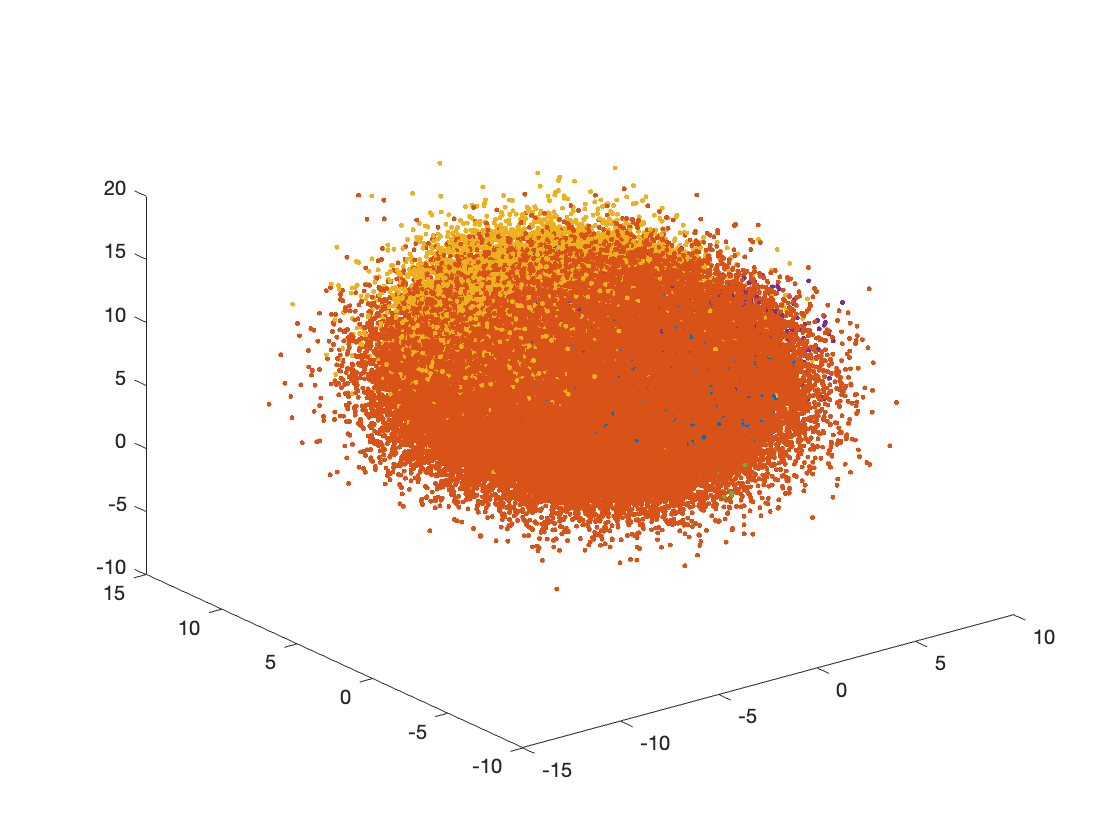

plot3(DA(:,1),DA(:,2),DA(:,3),'Marker',".","LineStyle","none")
hold on
plot3(DB(:,1),DB(:,2),DB(:,3),'Marker',".","LineStyle","none")
hold on
plot3(DC(:,1),DC(:,2),DC(:,3),'Marker',".","LineStyle","none")
hold on
plot3(DD(:,1),DD(:,2),DD(:,3),'Marker',".","LineStyle","none")
hold on
plot3(DE(:,1),DE(:,2),DE(:,3),'Marker',".","LineStyle","none")
hold off

### **2.Construct randomly (uniformly) selected training and test data set from the composite of your constructed 5 class data sets, where the training data should constitute 10% of the overall data and the test data the remaining 90% of the data. Record the number of train data samples for each of the training set classes as well as the exact indexes of the training and test data sample**

training_ratio = 0.1;
testing_ratio = 0.9;

idx = randperm(750000)  ;
training_classA = DA(idx(1:round(training_ratio * 750000)),:) ; 
testing_classA = DA(idx(round(training_ratio * 750000)+1:end),:) ;

idx = randperm(190000)  ;
training_classB = DB(idx(1:round(training_ratio * 190000)),:) ; 
testing_classB = DB(idx(round(training_ratio * 190000)+1:end),:) ;

idx = randperm(45000)  ;
training_classC = DC(idx(1:round(training_ratio * 45000)),:) ; 
testing_classC = DC(idx(round(training_ratio * 45000)+1:end),:) ;

idx = randperm(12000)  ;
training_classD = DD(idx(1:round(training_ratio * 12000)),:) ; 
testing_classD = DD(idx(round(training_ratio * 12000)+1:end),:) ;

idx = randperm(3000)  ;
training_classE = DE(idx(1:round(training_ratio * 3000)),:) ; 
testing_classE = DE(idx(round(training_ratio * 3000)+1:end),:) ;

training_data = [training_classA;training_classB;training_classC;training_classD;training_classE];
testing_data = [testing_classA;testing_classB;testing_classC;testing_classD;testing_classE];
label_A = [1, 0, 0, 0, 0];
label_B = [0, 1, 0, 0, 0];
label_C = [0, 0, 1, 0, 0];
label_D = [0, 0, 0, 1, 0];
label_E = [0, 0, 0, 0, 1];

training_label = [repmat(label_A, training_ratio * 750000, 1); repmat(label_B, training_ratio * 190000, 1); repmat(label_C, training_ratio * 45000, 1); repmat(label_D, training_ratio * 12000, 1); repmat(label_E, training_ratio * 3000, 1)]

training_label =      1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0


testing_label = [repmat(label_A, testing_ratio * 750000, 1); repmat(label_B, testing_ratio * 190000, 1); repmat(label_C, testing_ratio * 45000, 1); repmat(label_D, testing_ratio * 12000, 1); repmat(label_E, testing_ratio * 3000, 1)]

testing_label =      1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0


### **3. Use the training data sets to build and a Bayes and neural network classifier for this data.**

%Bayes
prior_A = length(training_classA)/ length(training_data);
prior_B = length(training_classB)/ length(training_data);
prior_C = length(training_classC)/ length(training_data);
prior_D = length(training_classD)/ length(training_data);
prior_E = length(training_classE)/ length(training_data);


% Mean for each class
mean_training_A = mean(training_classA, 1);
mean_training_B = mean(training_classB, 1);
mean_training_C = mean(training_classC, 1);
mean_training_D = mean(training_classD, 1);
mean_training_E = mean(training_classE, 1);

% Covaraince for each class
cov_training_A = cov(training_classA);
cov_training_B = cov(training_classB);
cov_training_C = cov(training_classC);
cov_training_D = cov(training_classD);
cov_training_E = cov(training_classE);


% discriminant function 
gk_A = discriment_f(testing_data,prior_A,mean_training_A , cov_training_A);
gk_B = discriment_f(testing_data,prior_B,mean_training_B , cov_training_B);
gk_C = discriment_f(testing_data,prior_C,mean_training_C , cov_training_C);
gk_D = discriment_f(testing_data,prior_D,mean_training_D , cov_training_D);
gk_E = discriment_f(testing_data,prior_E,mean_training_E , cov_training_E);



%nerual network
data = [training_data; testing_data]

data =    -1.5679    3.9624    7.6034
   -0.3719    4.5854    7.6519
   -0.8100    4.3395    2.0711
   -0.0482    2.9108    7.7580
    1.7168    3.1856    6.6307
    0.4701    3.5135    8.0395
    2.5040    3.5977    5.4242
   -1.3315    4.5741    7.9593
    0.2370    4.0662    6.8271
    0.7466    4.9006    4.6766


Targets = [training_label; testing_label]

Targets =      1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0



x = data';
t = Targets';

% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net = patternnet(hiddenLayerSize);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 100/100;
%net.divideParam.testRatio = 75/100;

% Train the Network
[net,tr] = train(net,x,t);

% Test the Network
y = net(x);
e = gsubtract(t,y);
performance = perform(net,t,y)

performance = 0.0933

tind = vec2ind(t);
yind = vec2ind(y);
percentErrors = sum(tind ~= yind)/numel(tind)

percentErrors = 0.1545

### **4. Apply the testing data to assess the per-class performance of your constructed classifiers.**

#### **Performance of Bayes Classifier to tetsing data**

% Index array for each class
index_A_Bayes = find(gk_A > gk_B & gk_A > gk_C & gk_A > gk_D & gk_A > gk_E);
index_B_Bayes = find(gk_B > gk_A & gk_B > gk_C & gk_B > gk_D & gk_B > gk_E);
index_C_Bayes = find(gk_C > gk_A & gk_C > gk_B & gk_C > gk_D & gk_C > gk_E);
index_D_Bayes = find(gk_D > gk_A & gk_D > gk_B & gk_D > gk_C & gk_D > gk_E);
index_E_Bayes = find(gk_E > gk_A & gk_E > gk_B & gk_E > gk_C & gk_E > gk_D);

% Present result labels of testing data set
label = repmat([0, 0, 0, 0, 0], length(testing_data), 1);
label(index_A_Bayes, 1) = 1; 
label(index_B_Bayes, 2) = 1;
label(index_C_Bayes, 3) = 1;
label(index_D_Bayes, 4) = 1;
label(index_E_Bayes, 5) = 1;
result_label_Bayes_testing = label; 

% Compare original labels and result labels
correct_clf_Bayes = sum(result_label_Bayes_testing .* testing_label); 
fprintf('')
fprintf('Testing Data Performance for Bayes Classifier')

Testing Data Performance for Bayes Classifier

fprintf('---------------------------------------------------------')

---------------------------------------------------------

correct_clf_Bayes_A = correct_clf_Bayes(1)

correct_clf_Bayes_A = 653816

correct_clf_Bayes_B = correct_clf_Bayes(2)

correct_clf_Bayes_B = 98213

correct_clf_Bayes_C = correct_clf_Bayes(3)

correct_clf_Bayes_C = 6974

correct_clf_Bayes_D = correct_clf_Bayes(4)

correct_clf_Bayes_D = 1943

correct_clf_Bayes_E = correct_clf_Bayes(5)

correct_clf_Bayes_E = 0


correct_clf_Bayes_A_ratio = correct_clf_Bayes(1) / (testing_ratio*750000)

correct_clf_Bayes_A_ratio = 0.9686

correct_clf_Bayes_B_ratio = correct_clf_Bayes(2) / (testing_ratio*190000)

correct_clf_Bayes_B_ratio = 0.5743

correct_clf_Bayes_C_ratio = correct_clf_Bayes(3) / (testing_ratio*45000)

correct_clf_Bayes_C_ratio = 0.1722

correct_clf_Bayes_D_ratio = correct_clf_Bayes(4) / (testing_ratio*12000)

correct_clf_Bayes_D_ratio = 0.1799

correct_clf_Bayes_E_ratio = correct_clf_Bayes(5) / (testing_ratio*3000)

correct_clf_Bayes_E_ratio = 0


correct_all_clf_Bayes_ratio = (length(testing_data) - sum(not(sum(result_label_Bayes_testing .* testing_label, 2)))) / length(testing_label)

correct_all_clf_Bayes_ratio = 0.8455

fprintf('---------------------------------------------------------')

---------------------------------------------------------

**Performance of NN to tetsing data**

outputs = net(testing_data');
result = outputs';

index_A_NN = find(result(:, 1) > result(:, 2) & result(:, 1) > result(:, 3) & result(:, 1) > result(:, 4) & result(:, 1) > result(:, 5));
index_B_NN = find(result(:, 2) > result(:, 1) & result(:, 2) > result(:, 3) & result(:, 2) > result(:, 4) & result(:, 2) > result(:, 5));
index_C_NN = find(result(:, 3) > result(:, 1) & result(:, 3) > result(:, 2) & result(:, 3) > result(:, 4) & result(:, 3) > result(:, 5));
index_D_NN = find(result(:, 4) > result(:, 1) & result(:, 4) > result(:, 2) & result(:, 4) > result(:, 3) & result(:, 4) > result(:, 5));
index_E_NN = find(result(:, 5) > result(:, 1) & result(:, 5) > result(:, 2) & result(:, 5) > result(:, 3) & result(:, 5) > result(:, 4));

label = repmat([0, 0, 0, 0, 0], length(testing_data), 1);
label(index_A_NN, 1) = 1; 
label(index_B_NN, 2) = 1;
label(index_C_NN, 3) = 1;
label(index_D_NN, 4) = 1;
label(index_E_NN, 5) = 1;
result_label_NN_testing = label; 

% Compare original labels and result labels 
correct_clf_NN = sum(result_label_NN_testing .* testing_label);
fprintf('\n')
fprintf('Testing Data Performance for Neural Network Classifier')

Testing Data Performance for Neural Network Classifier

fprintf('---------------------------------------------------------')

---------------------------------------------------------

correct_clf_NN_A = correct_clf_NN(1)

correct_clf_NN_A = 653631

correct_clf_NN_B = correct_clf_NN(2)

correct_clf_NN_B = 98130

correct_clf_NN_C = correct_clf_NN(3)

correct_clf_NN_C = 6937

correct_clf_NN_D = correct_clf_NN(4)

correct_clf_NN_D = 2030

correct_clf_NN_E = correct_clf_NN(5)

correct_clf_NN_E = 0


correct_clf_NN_A_ratio = correct_clf_NN(1) / (testing_ratio*750000)

correct_clf_NN_A_ratio = 0.9683

correct_clf_NN_B_ratio = correct_clf_NN(2) / (testing_ratio*190000)

correct_clf_NN_B_ratio = 0.5739

correct_clf_NN_C_ratio = correct_clf_NN(3) / (testing_ratio*45000)

correct_clf_NN_C_ratio = 0.1713

correct_clf_NN_D_ratio = correct_clf_NN(4) / (testing_ratio*12000)

correct_clf_NN_D_ratio = 0.1880

correct_clf_NN_E_ratio = correct_clf_NN(5) / (testing_ratio*3000)

correct_clf_NN_E_ratio = 0


correct_all_clf_NN_ratio = (length(testing_data) - sum(not(sum(result_label_NN_testing .* testing_label, 2)))) / length(testing_data)

correct_all_clf_NN_ratio = 0.8453

fprintf('---------------------------------------------------------')

---------------------------------------------------------

### **5. Discuss the similarities and differences that the unbalanced data sets have on the in sensitivity and robustness of your constructed classifiers and their training versus test set performances. Which types of classification approaches are more robust to unbalanced data sets (and why?) neural network type approaches or Bayes-like approaches, i.e., nonparametric approaches or parametric approaches?**

#### **Performance of Bayes Classifier to training data**

gk_A = discriment_f(training_data,prior_A,mean_training_A , cov_training_A);
gk_B = discriment_f(training_data,prior_B,mean_training_B , cov_training_B);
gk_C = discriment_f(training_data,prior_C,mean_training_C , cov_training_C);
gk_D = discriment_f(training_data,prior_D,mean_training_D , cov_training_D);
gk_E = discriment_f(training_data,prior_E,mean_training_E , cov_training_E);



% Index array for each class
index_A_Bayes = find(gk_A > gk_B & gk_A > gk_C & gk_A > gk_D & gk_A > gk_E);
index_B_Bayes = find(gk_B > gk_A & gk_B > gk_C & gk_B > gk_D & gk_B > gk_E);
index_C_Bayes = find(gk_C > gk_A & gk_C > gk_B & gk_C > gk_D & gk_C > gk_E);
index_D_Bayes = find(gk_D > gk_A & gk_D > gk_B & gk_D > gk_C & gk_D > gk_E);
index_E_Bayes = find(gk_E > gk_A & gk_E > gk_B & gk_E > gk_C & gk_E > gk_D);

% Present result labels of testing data set
label = repmat([0, 0, 0, 0, 0], length(training_data), 1);
label(index_A_Bayes, 1) = 1; 
label(index_B_Bayes, 2) = 1;
label(index_C_Bayes, 3) = 1;
label(index_D_Bayes, 4) = 1;
label(index_E_Bayes, 5) = 1;
result_label_Bayes_training = label; 

% Compare original labels and result labels
correct_clf_Bayes = sum(result_label_Bayes_training .* training_label); 
fprintf('')
fprintf('Training Data Performance for Bayes Classifier')

Training Data Performance for Bayes Classifier

fprintf('---------------------------------------------------------')

---------------------------------------------------------

correct_clf_Bayes_A = correct_clf_Bayes(1)

correct_clf_Bayes_A = 72711

correct_clf_Bayes_B = correct_clf_Bayes(2)

correct_clf_Bayes_B = 11019

correct_clf_Bayes_C = correct_clf_Bayes(3)

correct_clf_Bayes_C = 804

correct_clf_Bayes_D = correct_clf_Bayes(4)

correct_clf_Bayes_D = 220

correct_clf_Bayes_E = correct_clf_Bayes(5)

correct_clf_Bayes_E = 0


correct_clf_Bayes_A_ratio = correct_clf_Bayes(1) / (training_ratio*750000)

correct_clf_Bayes_A_ratio = 0.9695

correct_clf_Bayes_B_ratio = correct_clf_Bayes(2) / (training_ratio*190000)

correct_clf_Bayes_B_ratio = 0.5799

correct_clf_Bayes_C_ratio = correct_clf_Bayes(3) / (training_ratio*45000)

correct_clf_Bayes_C_ratio = 0.1787

correct_clf_Bayes_D_ratio = correct_clf_Bayes(4) / (training_ratio*12000)

correct_clf_Bayes_D_ratio = 0.1833

correct_clf_Bayes_E_ratio = correct_clf_Bayes(5) / (training_ratio*3000)

correct_clf_Bayes_E_ratio = 0


correct_all_clf_Bayes_ratio = (length(training_data) - sum(not(sum(result_label_Bayes_training .* training_label, 2)))) / length(training_label)

correct_all_clf_Bayes_ratio = 0.8475

fprintf('---------------------------------------------------------')

---------------------------------------------------------

**Performance of NN to tetsing data**

outputs = net(training_data');
result = outputs';

index_A_NN = find(result(:, 1) > result(:, 2) & result(:, 1) > result(:, 3) & result(:, 1) > result(:, 4) & result(:, 1) > result(:, 5));
index_B_NN = find(result(:, 2) > result(:, 1) & result(:, 2) > result(:, 3) & result(:, 2) > result(:, 4) & result(:, 2) > result(:, 5));
index_C_NN = find(result(:, 3) > result(:, 1) & result(:, 3) > result(:, 2) & result(:, 3) > result(:, 4) & result(:, 3) > result(:, 5));
index_D_NN = find(result(:, 4) > result(:, 1) & result(:, 4) > result(:, 2) & result(:, 4) > result(:, 3) & result(:, 4) > result(:, 5));
index_E_NN = find(result(:, 5) > result(:, 1) & result(:, 5) > result(:, 2) & result(:, 5) > result(:, 3) & result(:, 5) > result(:, 4));

label = repmat([0, 0, 0, 0, 0], length(training_data), 1);
label(index_A_NN, 1) = 1; 
label(index_B_NN, 2) = 1;
label(index_C_NN, 3) = 1;
label(index_D_NN, 4) = 1;
label(index_E_NN, 5) = 1;
result_label_NN_training = label; 

% Compare original labels and result labels 
correct_clf_NN = sum(result_label_NN_training .* training_label);
fprintf('\n')
fprintf('Training Data Performance for Neural Network Classifier')

Training Data Performance for Neural Network Classifier

fprintf('---------------------------------------------------------')

---------------------------------------------------------

correct_clf_NN_A = correct_clf_NN(1)

correct_clf_NN_A = 72680

correct_clf_NN_B = correct_clf_NN(2)

correct_clf_NN_B = 11028

correct_clf_NN_C = correct_clf_NN(3)

correct_clf_NN_C = 789

correct_clf_NN_D = correct_clf_NN(4)

correct_clf_NN_D = 231

correct_clf_NN_E = correct_clf_NN(5)

correct_clf_NN_E = 0


correct_clf_NN_A_ratio = correct_clf_NN(1) / (training_ratio*750000)

correct_clf_NN_A_ratio = 0.9691

correct_clf_NN_B_ratio = correct_clf_NN(2) / (training_ratio*190000)

correct_clf_NN_B_ratio = 0.5804

correct_clf_NN_C_ratio = correct_clf_NN(3) / (training_ratio*45000)

correct_clf_NN_C_ratio = 0.1753

correct_clf_NN_D_ratio = correct_clf_NN(4) / (training_ratio*12000)

correct_clf_NN_D_ratio = 0.1925

correct_clf_NN_E_ratio = correct_clf_NN(5) / (training_ratio*3000)

correct_clf_NN_E_ratio = 0


correct_all_clf_NN_ratio = (length(training_data) - sum(not(sum(result_label_NN_training .* training_label, 2)))) / length(training_data)

correct_all_clf_NN_ratio = 0.8473

fprintf('---------------------------------------------------------')

---------------------------------------------------------

### **Q5 Discussion **

**Similiarities**

Both Bayes classifier and Neural Network perfroms well on majority classes such as class A, but performs worse on minority classes such as class E. We can see from the experiment that performance on training data and tetsing data sets are very similiar.  Majority classes contains more information and high prior probability, this lead good performance for Bayes classifier and Neural Network in majority classes. 

**Differences**

When looking at performance of minority classes, Bayes classifier performs better than Neural Network. Netrual Network has rearly 0 correct classification for minority class (class E). Neural Network focus on what most data are, therefore it has poor performance on minority classes. But Bayes classifier also consider the prior probability for each class, this lead some improvement on classification for minority classes compare with Neural Network. 

**Neural Network vs Bayes-like approaches**

Neural Network are more sensitive to unbalanced data sets because Neural Network look at the entire dataset. And when we have unbalanced dataset, Neural Network will focus on majority class, and pay less attention on minority. Bayes classifier have condier prior probability for each class, and is more rubust to unbalanced dataset. . 

This makes Neural Network more sensitive to unbalanced data sets compare with Bayes classfier. And this also lead the overall classification accuracy for Bayes classfier better than Neural Network. 

### **6. Discuss the impacts that taking random draws from unbalanced data sets can have on training sets. For example, what percentage of the possible random (uniform) training set draws would consist of < 10 samples from Class E? What is the probability of such an event as a function of the number of available Class E data samples?**

total = 100000; % the number of all-class samples
E2 = 300; % the number of class E samples
p = E2 /total 

p = 0.0030

x = 7 

x = 7


% n_total is much larger than x, the binomial distribution remains a good approximation.
prob_event = binocdf(x, total, p)

prob_event = 1.4876e-117

In unbalanced data set, it is more likely to have majority classes such as class A, less likely to have minority classes such as class E. The probability of drawing class E samples from the population is only $\frac{300}{100000}=0\ldotp 003$.

If we take x samples randomly from training set, p = 0.03, n = 100000, the binomial probability will be $b\left(x;n,p\right)=1\ldotp 4876e-117$

Therefore, It is very unlikely for random (uniform) training set draws would consist of < 10 samples from Class E. 

### **7. Compare the performance of your classifiers to a second set of classifiers constructed from balanced training data, i.e., generate balanced perclass data sets and retrain your classifiers.**

idx_E = randperm(3000)  ;
% idx2 = randperm(750000)  ;
balanced_training_classA = DA(idx_E(1:round(training_ratio * 3000)),:) ; 
% balanced_testing_classA = DA(idx2(round(training_ratio * 750000)+1:end),:) ;

% idx2 = randperm(190000)  ;
balanced_training_classB = DB(idx_E(1:round(training_ratio * 3000)),:) ; 
% balanced_testing_classB = DB(idx2(round(training_ratio * 190000)+1:end),:) ;

% idx2 = randperm(45000)  ;
balanced_training_classC = DC(idx_E(1:round(training_ratio * 3000)),:) ; 
% balanced_testing_classC = DC(idx2(round(training_ratio * 45000)+1:end),:) ;

% idx2 = randperm(12000)  ;
balanced_training_classD = DD(idx_E(1:round(training_ratio * 3000)),:) ; 
% balanced_testing_classD = DD(idx2(round(training_ratio * 12000)+1:end),:) ;

% idx2 = randperm(3000)  ;
balanced_training_classE = DE(idx_E(1:round(training_ratio * 3000)),:) ; 
% balanced_testing_classE = DE(idx_E(round(training_ratio * 3000)+1:end),:) ;

balanced_training_data = [balanced_training_classA;balanced_training_classB;balanced_training_classC;balanced_training_classD;balanced_training_classE];
% balanced_testing_data = [balanced_testing_classA;balanced_testing_classB;balanced_testing_classC;balanced_testing_classD;balanced_testing_classE];
label_A = [1, 0, 0, 0, 0];
label_B = [0, 1, 0, 0, 0];
label_C = [0, 0, 1, 0, 0];
label_D = [0, 0, 0, 1, 0];
label_E = [0, 0, 0, 0, 1];

balanced_training_label = [repmat(label_A, training_ratio * 3000, 1); repmat(label_B, training_ratio * 3000, 1); repmat(label_C, training_ratio * 3000, 1); repmat(label_D, training_ratio * 3000, 1); repmat(label_E, training_ratio * 3000, 1)]

balanced_training_label =      1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0


% balanced_testing_label = [repmat(label_A, testing_ratio * 750000, 1); repmat(label_B, testing_ratio * 190000, 1); repmat(label_C, testing_ratio * 45000, 1); repmat(label_D, testing_ratio * 12000, 1); repmat(label_E, testing_ratio * 3000, 1)]


%Bayes
balanced_prior_A = length(balanced_training_classA)/ length(balanced_training_data);
balanced_prior_B = length(balanced_training_classB)/ length(balanced_training_data);
balanced_prior_C = length(balanced_training_classC)/ length(balanced_training_data);
balanced_prior_D = length(balanced_training_classD)/ length(balanced_training_data);
balanced_prior_E = length(balanced_training_classE)/ length(balanced_training_data);


% Mean for each class
balanced_mean_training_A = mean(balanced_training_classA, 1);
balanced_mean_training_B = mean(balanced_training_classB, 1);
balanced_mean_training_C = mean(balanced_training_classC, 1);
balanced_mean_training_D = mean(balanced_training_classD, 1);
balanced_mean_training_E = mean(balanced_training_classE, 1);

% Covaraince for each class
balanced_cov_training_A = cov(balanced_training_classA);
balanced_cov_training_B = cov(balanced_training_classB);
balanced_cov_training_C = cov(balanced_training_classC);
balanced_cov_training_D = cov(balanced_training_classD);
balanced_cov_training_E = cov(balanced_training_classE);


% discriminant function 
balanced_gk_A = discriment_f(testing_data,balanced_prior_A,balanced_mean_training_A , balanced_cov_training_A)

balanced_gk_A =    -4.5435
   -3.6255
   -5.4185
   -3.3356
   -3.6017
   -3.4479
   -4.1073
   -4.2141
   -4.3039
   -3.8320


balanced_gk_B = discriment_f(testing_data,balanced_prior_B,balanced_mean_training_B , balanced_cov_training_B)

balanced_gk_B =    -5.8704
   -5.3006
   -8.2326
   -5.9127
   -4.5447
   -4.6670
   -4.7055
   -5.1438
   -4.7718
   -5.1327


balanced_gk_C = discriment_f(testing_data,balanced_prior_C,balanced_mean_training_C , balanced_cov_training_C)

balanced_gk_C =    -4.8938
   -5.1579
   -4.7571
   -4.6666
   -5.1760
   -4.8812
   -5.9356
   -6.3652
   -4.7567
   -6.0548


balanced_gk_D = discriment_f(testing_data,balanced_prior_D,balanced_mean_training_D , balanced_cov_training_D)

balanced_gk_D =    -4.7574
   -3.9143
   -8.9463
   -4.0044
   -5.1379
   -5.2501
   -4.8466
   -4.2486
   -6.1409
   -3.9134


balanced_gk_E = discriment_f(testing_data,balanced_prior_E,balanced_mean_training_E , balanced_cov_training_E)

balanced_gk_E =   -11.9751
   -8.6225
   -3.9698
   -3.0199
   -6.2180
   -5.9337
  -11.7782
  -10.1908
  -13.2337
   -3.5169


%nerual network
balanced_data = [balanced_training_data; testing_data]

balanced_data =    -2.0883    4.9328    6.7903
    0.2414    2.6060    8.5482
   -0.5016    2.8182    5.1182
   -1.4136    2.2078    6.4572
   -1.4590    6.1949    8.0640
   -0.2750    1.6820    5.7169
   -1.3897    3.4065    6.9980
   -2.3746    5.4910    5.4274
   -2.1507    0.1089    6.6179
   -0.7273    5.5959    4.9569


balanced_Targets = [balanced_training_label; testing_label]

balanced_Targets =      1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0
     1     0     0     0     0



x = balanced_data';
t = balanced_Targets';


% Create a Pattern Recognition Network
hiddenLayerSize = 10;
net2 = patternnet(hiddenLayerSize);

% Setup Division of Data for Training, Validation, Testing
net2.divideParam.trainRatio = 25/100;
%net.divideParam.testRatio = 75/100;

% Train the Network
[net2,tr] = train(net2,x,t);

% Test the Network
y = net2(x)

y =     0.9842    0.5672    0.8320    0.9725    0.8806    0.9018    0.8488    0.6262    0.5008    0.8489    0.7348    0.8973    0.9669    0.9195    0.8405    0.9306    0.9382    0.8791    0.9017    0.9817    0.7733    0.8574    0.7709    0.9139    0.9731    0.8007    0.9063    0.9007    0.9468    0.8645    0.6700    0.9263    0.9379    0.9810    0.7996    0.7665    0.6789    0.8976    0.9402    0.9691    0.9738    0.9809    0.7357    0.9137    0.9324    0.9716    0.9082    0.9254    0.8876    0.7917
    0.0106    0.3335    0.0969    0.0209    0.0541    0.0864    0.0566    0.2619    0.2949    0.0888    0.1699    0.0578    0.0271    0.0476    0.0657    0.0403    0.0352    0.0763    0.0702    0.0117    0.1044    0.0636    0.0440    0.0649    0.0141    0.1361    0.0288    0.0950    0.0397    0.0899    0.1108    0.0649    0.0547    0.0153    0.1679    0.1480    0.2380    0.0855    0.0278    0.0128    0.0213    0.0167    0.1125    0.0358    0.0166    0.0221    0.0780    0.0510    0.1069    0

e = gsubtract(t,y)

e =     0.0158    0.4328    0.1680    0.0275    0.1194    0.0982    0.1512    0.3738    0.4992    0.1511    0.2652    0.1027    0.0331    0.0805    0.1595    0.0694    0.0618    0.1209    0.0983    0.0183    0.2267    0.1426    0.2291    0.0861    0.0269    0.1993    0.0937    0.0993    0.0532    0.1355    0.3300    0.0737    0.0621    0.0190    0.2004    0.2335    0.3211    0.1024    0.0598    0.0309    0.0262    0.0191    0.2643    0.0863    0.0676    0.0284    0.0918    0.0746    0.1124    0.2083
   -0.0106   -0.3335   -0.0969   -0.0209   -0.0541   -0.0864   -0.0566   -0.2619   -0.2949   -0.0888   -0.1699   -0.0578   -0.0271   -0.0476   -0.0657   -0.0403   -0.0352   -0.0763   -0.0702   -0.0117   -0.1044   -0.0636   -0.0440   -0.0649   -0.0141   -0.1361   -0.0288   -0.0950   -0.0397   -0.0899   -0.1108   -0.0649   -0.0547   -0.0153   -0.1679   -0.1480   -0.2380   -0.0855   -0.0278   -0.0128   -0.0213   -0.0167   -0.1125   -0.0358   -0.0166   -0.0221   -0.0780   -0.0510   -0.1069   -0

performance = perform(net2,t,y)

performance = 0.1055

tind = vec2ind(t);
yind = vec2ind(y);
percentErrors = sum(tind ~= yind)/numel(tind)

percentErrors = 0.1832

% Index array for each class
balanced_index_A_Bayes = find(balanced_gk_A > balanced_gk_B & balanced_gk_A > balanced_gk_C & balanced_gk_A > balanced_gk_D & balanced_gk_A > balanced_gk_E);
balanced_index_B_Bayes = find(balanced_gk_B > balanced_gk_A & balanced_gk_B > balanced_gk_C & balanced_gk_B > balanced_gk_D & balanced_gk_B > balanced_gk_E);
balanced_index_C_Bayes = find(balanced_gk_C > balanced_gk_A & balanced_gk_C > balanced_gk_B & balanced_gk_C > balanced_gk_D & balanced_gk_C > balanced_gk_E);
balanced_index_D_Bayes = find(balanced_gk_D > balanced_gk_A & balanced_gk_D > balanced_gk_B & balanced_gk_D > balanced_gk_C & balanced_gk_D > balanced_gk_E);
balanced_index_E_Bayes = find(balanced_gk_E > balanced_gk_A & balanced_gk_E > balanced_gk_B & balanced_gk_E > balanced_gk_C & balanced_gk_E > balanced_gk_D);

% Present result labels of testing data set
label = repmat([0, 0, 0, 0, 0], length(balanced_testing_data), 1);
label(balanced_index_A_Bayes, 1) = 1; 
label(balanced_index_B_Bayes, 2) = 1;
label(balanced_index_C_Bayes, 3) = 1;
label(balanced_index_D_Bayes, 4) = 1;
label(balanced_index_E_Bayes, 5) = 1;
balanced_result_label_Bayes_testing = label; 

% Compare original labels and result labels
balanced_correct_clf_Bayes = sum(balanced_result_label_Bayes_testing .* testing_label); 
fprintf('')
fprintf('Q7 Testing Data Performance for Bayes Classifier')

Q7 Testing Data Performance for Bayes Classifier

fprintf('---------------------------------------------------------')

---------------------------------------------------------

balanced_correct_clf_Bayes_A = balanced_correct_clf_Bayes(1)

balanced_correct_clf_Bayes_A = 394254

balanced_correct_clf_Bayes_B = balanced_correct_clf_Bayes(2)

balanced_correct_clf_Bayes_B = 116073

balanced_correct_clf_Bayes_C = balanced_correct_clf_Bayes(3)

balanced_correct_clf_Bayes_C = 24381

balanced_correct_clf_Bayes_D = balanced_correct_clf_Bayes(4)

balanced_correct_clf_Bayes_D = 8861

balanced_correct_clf_Bayes_E = balanced_correct_clf_Bayes(5)

balanced_correct_clf_Bayes_E = 1348


balanced_correct_clf_Bayes_A_ratio = balanced_correct_clf_Bayes(1) / (testing_ratio*750000)

balanced_correct_clf_Bayes_A_ratio = 0.5841

balanced_correct_clf_Bayes_B_ratio = balanced_correct_clf_Bayes(2) / (testing_ratio*190000)

balanced_correct_clf_Bayes_B_ratio = 0.6788

balanced_correct_clf_Bayes_C_ratio = balanced_correct_clf_Bayes(3) / (testing_ratio*45000)

balanced_correct_clf_Bayes_C_ratio = 0.6020

balanced_correct_clf_Bayes_D_ratio = balanced_correct_clf_Bayes(4) / (testing_ratio*12000)

balanced_correct_clf_Bayes_D_ratio = 0.8205

balanced_correct_clf_Bayes_E_ratio = balanced_correct_clf_Bayes(5) / (testing_ratio*3000)

balanced_correct_clf_Bayes_E_ratio = 0.4993


balanced_correct_all_clf_Bayes_ratio = (length(testing_data) - sum(not(sum(balanced_result_label_Bayes_testing .* testing_label, 2)))) / length(testing_label)

balanced_correct_all_clf_Bayes_ratio = 0.6055

fprintf('Q7---------------------------------------------------------')

Q7---------------------------------------------------------

**Performance of NN to tetsing data**

outputs = net2(balanced_testing_data');
result = outputs';

index_A_NN = find(result(:, 1) > result(:, 2) & result(:, 1) > result(:, 3) & result(:, 1) > result(:, 4) & result(:, 1) > result(:, 5));
index_B_NN = find(result(:, 2) > result(:, 1) & result(:, 2) > result(:, 3) & result(:, 2) > result(:, 4) & result(:, 2) > result(:, 5));
index_C_NN = find(result(:, 3) > result(:, 1) & result(:, 3) > result(:, 2) & result(:, 3) > result(:, 4) & result(:, 3) > result(:, 5));
index_D_NN = find(result(:, 4) > result(:, 1) & result(:, 4) > result(:, 2) & result(:, 4) > result(:, 3) & result(:, 4) > result(:, 5));
index_E_NN = find(result(:, 5) > result(:, 1) & result(:, 5) > result(:, 2) & result(:, 5) > result(:, 3) & result(:, 5) > result(:, 4));

label = repmat([0, 0, 0, 0, 0], length(testing_data), 1);
label(index_A_NN, 1) = 1; 
label(index_B_NN, 2) = 1;
label(index_C_NN, 3) = 1;
label(index_D_NN, 4) = 1;
label(index_E_NN, 5) = 1;
result_label_NN_testing = label; 

% Compare original labels and result labels 
correct_clf_NN = sum(result_label_NN_testing .* testing_label);
fprintf('\n')
fprintf('Q7 Testing Data Performance for Neural Network Classifier')

Q7 Testing Data Performance for Neural Network Classifier

fprintf('---------------------------------------------------------')

---------------------------------------------------------

correct_clf_NN_A = correct_clf_NN(1)

correct_clf_NN_A = 651701

correct_clf_NN_B = correct_clf_NN(2)

correct_clf_NN_B = 84445

correct_clf_NN_C = correct_clf_NN(3)

correct_clf_NN_C = 8

correct_clf_NN_D = correct_clf_NN(4)

correct_clf_NN_D = 0

correct_clf_NN_E = correct_clf_NN(5)

correct_clf_NN_E = 0


correct_clf_NN_A_ratio = correct_clf_NN(1) / (testing_ratio*750000)

correct_clf_NN_A_ratio = 0.9655

correct_clf_NN_B_ratio = correct_clf_NN(2) / (testing_ratio*190000)

correct_clf_NN_B_ratio = 0.4938

correct_clf_NN_C_ratio = correct_clf_NN(3) / (testing_ratio*45000)

correct_clf_NN_C_ratio = 1.9753e-04

correct_clf_NN_D_ratio = correct_clf_NN(4) / (testing_ratio*12000)

correct_clf_NN_D_ratio = 0

correct_clf_NN_E_ratio = correct_clf_NN(5) / (testing_ratio*3000)

correct_clf_NN_E_ratio = 0


correct_all_clf_NN_ratio = (length(testing_data) - sum(not(sum(result_label_NN_testing .* testing_label, 2)))) / length(testing_data)

correct_all_clf_NN_ratio = 0.8179

fprintf('Q7 ---------------------------------------------------------')

Q7 ---------------------------------------------------------

Both Bayes classifier and Neural Network has imporved for classification minority classes, but the performance of majority classes decreased. As the sample for majority classes are decrease to the same sample size as minority classes, some information for majority classes are missed. 

### **8. Unbalanced data sets occur commonly in real-world data analysis problems e.g., in cyber-security normal network traffic events typically outnumber malicious events by many orders of magnitude. Discuss some of the possible approaches that could be applied to address the problem. Note, in general, it may not be possible or feasible to simple collects sufficient data from each representative data class such that the training data with high likelihood is sufficiently balanced.**

There are many approaches to handle unbalanced data sets. 

1.Change evalution metrics. We can use sensitivity and specificity to meaure the performance of model. 

- sensitivity=number of true positives/(number of true positives+number of false negatives).              

- specificity=number of true negatives/(number of true negatives+number of false positives). 

By using these two evaluation metrics, the performance can be well measured. 

2. Resample the dataset

- under-sampling. Under-sampling balances the dataset by reducing the size of the majority class. It will have balanced new dataset. 

- over-sampling. It tries to balance dataset by increasing the size of minority class. 

3. Change class weights in the models. In different machine learning models, we can specify a higher weight for the minority class. 

### **9. Can unbalanced data sets be easily identified in real-world data analytics problems (why or why not)?**

If the data sets have given class labels, then it will easily identify if unbalanced data sets exist. However if there are no class labels given, it may hard to identify unbalanced data set in real-world data analytics problem. 

function dataset = dataset_generator(dimension, K, x_rot, y_rot, z_rot)

    mean_value = rand(dimension, 1) * 10 - 5;
    scale = rand(dimension, 1) * 10 .* eye(dimension);
    rotate = eye(dimension) * rotx(x_rot) * roty(y_rot) * rotz(z_rot);
    cov_value = rotate * scale * rotate'; 
    dataset = Gaussion_Data(K,dimension,mean_value, cov_value)
end

Function to crete n-dimensional Gaussian data sets 

function data = Gaussion_Data(k, d, mu, cov)

data  = randn(k,d);
[E,v] = eigs(cov);
data = v^(1/2) * E * data.';

data = data.' + mu;
end



function transform = trans(data,m,sigma)
%     [e2, v2] = eig(cov(data));
%     A = e2 * 1/sqrt(v2);
%     transform = data * A;

%%whitening transformation to get covariance matrix to identity matrix. 
data = data-mean(data);
[E,v] = eigs(cov(data));
Y = E*v^(-1/2);
X = data * Y;

%%coloring transformation to get the exact mean and covariance matrix. 
[E1,v1] = eigs(sigma);
Y = v1^(1/2) * X';
transform = E1 * Y;
transform = transform'+m;
end


function g_x = discriment_f(x,prior_prob, mu, sigma)
% discriment function follows from equation 67 in Ch2.
W_i = (-1/2)*inv(sigma);
w_i = inv(sigma)*mu';
w_i_0 = (-1/2)*mu*inv(sigma)*mu' - (1/2)*log(det(sigma))+log(prior_prob);
g_x = sum((x*W_i.').*x,2).'+w_i'*x'+w_i_0;
g_x = g_x.';


end